class1 = 'TURMER';
class2 = 'LUSMEG';

[XTrain, YTrain] = createFeatureCells(TURMER_train40,LUSMEG_train40,class1,class2);

Unrecognized function or variable 'TURMER_train40'.

XTrainFs = vertcat(TURMER_trainFs40,LUSMEG_trainFs40);
[XTest, YTest] = createFeatureCells(TURMER_test40,LUSMEG_test40,class1,class2);
XTestFs = vertcat(TURMER_testFs40,LUSMEG_testFs40);

XTrainMfccBase = cellfun(@(a,b) extractMfcc(a,b),XTrain,XTrainFs,"UniformOutput",false);

XTrainMfccNumeric = cell2Matrix(XTrainMfccBase);

[XTrainMfcc,YTrainMfcc,XValMfcc,YValMfcc] = createValidationSplit(XTrainMfccNumeric,YTrain,"Split",0.05);

XTestMfccBase = cellfun(@(a,b) extractMfcc(a,b),XTest,XTestFs,"UniformOutput",false);
XTestMfccNumeric = cell2Matrix(XTestMfccBase);

cnnMfccEvalCell = {};

## Model 0

### MFCC

layers0 = [...
    imageInputLayer(size(XTrainMfccNumeric,[1 2 3]))
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
];

maxEpochs = 30;
options0 = trainingOptions("adam", ...
    "MiniBatchSize",128, ...
    "Plots","training-progress", ...
    "MaxEpochs",maxEpochs, ...
    "ValidationData",{XValMfcc,YValMfcc}, ...
    "Verbose",0);

cnn0 = trainNetwork(XTrainMfcc,YTrainMfcc,layers0,options0);

analyzeNetwork(cnn0)

~3s per epoch

eval0 = generateEvaluationCell(cnn0,0,XTestMfccNumeric,YTest,class1);
cnnMfccEvalCell = [cnnMfccEvalCell;eval0];

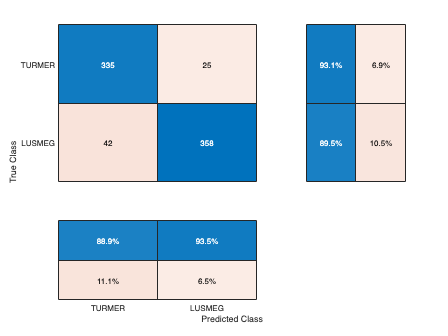

YPred = classify(cnn0,XTestMfccNumeric);
cm = confusionchart(YTest,YPred);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

cm

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties


## Model 1: Ruff et al.

layers1 = [...
    imageInputLayer(size(XTrainMfccNumeric,[1 2 3]))
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2)
    dropoutLayer(0.2)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2)
    dropoutLayer(0.2)
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2)
    dropoutLayer(0.2)
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2)
    dropoutLayer(0.2)
    fullyConnectedLayer(64)
    reluLayer
    dropoutLayer(0.5)
    batchNormalizationLayer
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
];

maxEpochs = 30;
options1 = trainingOptions("adam", ...
    "MiniBatchSize",128, ...
    "Plots","training-progress", ...
    "MaxEpochs",maxEpochs, ...
    "ValidationData",{XValMfcc,YValMfcc}, ...
    "Verbose",0);

cnn1 = trainNetwork(XTrainMfcc,YTrainMfcc,layers1,options1);

eval1 = generateEvaluationCell(cnn1,1,XTestMfccNumeric,YTest,class1);
cnnMfccEvalCell = [cnnMfccEvalCell;eval1];

## Model 2: Kahl et al.

layers2 = [...
    imageInputLayer(size(XTrainMfccNumeric,[1 2 3]))
    convolution2dLayer(7,32,'WeightsInitializer','he','Stride',2,'Padding','same')
    batchNormalizationLayer
    eluLayer
    maxPooling2dLayer(2)
    dropoutLayer(0.2)
    convolution2dLayer(5,128,'WeightsInitializer','he','Stride',1,'Padding','same')
    batchNormalizationLayer
    eluLayer
    maxPooling2dLayer(2)
    convolution2dLayer(3,256,'WeightsInitializer','he','Stride',1,'Padding','same')
    batchNormalizationLayer
    eluLayer
    maxPooling2dLayer(2)
    convolution2dLayer(3,512,'WeightsInitializer','he','Stride',1,'Padding','same')
    batchNormalizationLayer
    eluLayer
    maxPooling2dLayer(2)
    convolution2dLayer(3,512,'WeightsInitializer','he','Stride',1,'Padding','same')
    batchNormalizationLayer
    eluLayer
    maxPooling2dLayer(2)
    fullyConnectedLayer(512,'WeightsInitializer','he')
    dropoutLayer(0.5)
    fullyConnectedLayer(512,'WeightsInitializer','he')
    dropoutLayer(0.5)
    batchNormalizationLayer
    eluLayer
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
];

maxEpochs = 30;
options2 = trainingOptions("adam", ...
    "MiniBatchSize",128, ...
    "Plots","training-progress", ...
    "MaxEpochs",maxEpochs, ...
    "L2Regularization",0.0001, ...
    "InitialLearnRate",0.01, ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropPeriod",1, ...
    "LearnRateDropFactor",exp(log(0.001)/maxEpochs), ...
    "ValidationData",{XValMfcc,YValMfcc}, ...
    "Verbose",0);

cnn2 = trainNetwork(XTrainMfcc,YTrainMfcc,layers2,options2);

Stopped early since training and validation accuracy had plateaued (around 99% validation accuracy). Stopped at 15/30 epochs. 

~165s per epoch

eval2 = generateEvaluationCell(cnn2,2,XTestMfccNumeric,YTest,class1);
cnnMfccEvalCell = [cnnMfccEvalCell;eval2];

cnnMfccEvalData = zeros(3,2);
for i = 1:3
    cnnMfccEvalData(i,1) = cnnMfccEvalCell{i,2};
    cnnMfccEvalData(i,2) = cnnMfccEvalCell{i,3};
end

figure;
bar(0:2,cnnMfccEvalData)
ylim([0 1])
legend({'AUC','Accuracy'},"Location","southeast")
xlabel('Model number')

function mfccFeature = extractMfcc(signal,fs)
[coeffs, delta, ddelta, ~] = mfcc(signal,fs);
mfccFeature = [coeffs;delta;ddelta];
end

function matrix = cell2Matrix(cell)
matrix = zeros(size(cell{1},1),size(cell{1},2),1,numel(cell));
for row = 1:numel(cell)
matrix(:,:,1,row) = cell{row};
end
end

function [XTrain, YTrain, XValidation, YValidation] = createValidationSplit(X, Y, nva)
arguments
X
Y
nva.Split = 0.3
end

numSamples = size(X, 4);

cv = cvpartition(numSamples, 'HoldOut', nva.Split);
trainIndices = training(cv);
validationIndices = test(cv);

XTrain = X(:,:,1,trainIndices);
YTrain = Y(trainIndices);

XValidation = X(:,:,1,validationIndices);
YValidation = Y(validationIndices);
end

function evalCell = generateEvaluationCell(model,archNumber,XTest,YTest,posClass)
[auc,accuracy,ROCX,ROCY] = evaluateNN(model,XTest,YTest,posClass);
evalCell = {archNumber,auc,accuracy,ROCX,ROCY};
end